## square rectangle

### simplest form

vert1 = rectangleVert(1);
plot(polyshape(vert1'));
axSetup(); axis equal; hold on;
vert1 = rectangleVert(1,'loop','tight');

### coordinate system in the center, no extra vertices

vert2 = rectangleVert(1,'coordinateSystem','center','density',0);

#### different spelling

vert3 = rectangleVert(1,'coordinateSystem','centre','density',0);

#### different spelling

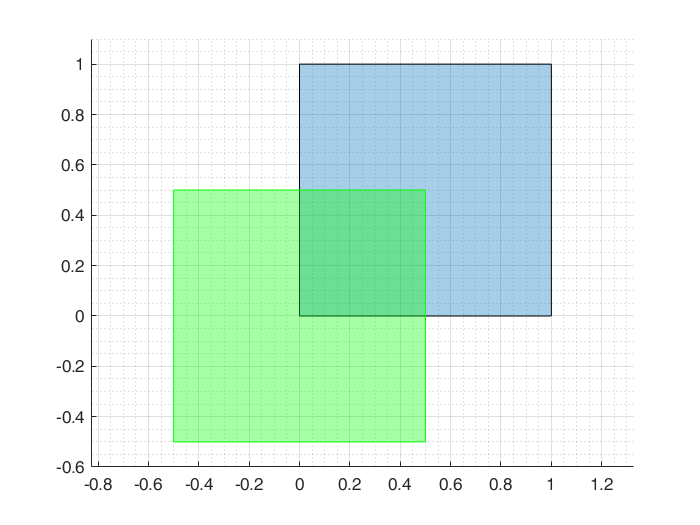

vert3 = rectangleVert(1,'coordinateSystem','c','density',0);
plot(polyshape(vert3'),'FaceColor','g','EdgeColor','g');
hold off;

### force coordinate system to lower left

vert4 = rectangleVert(1,'coordinateSystem','lowerleft','density',0);

#### different spelling

vert4 = rectangleVert(1,'coordinateSystem','ll','density',0);

## non-square rectangle

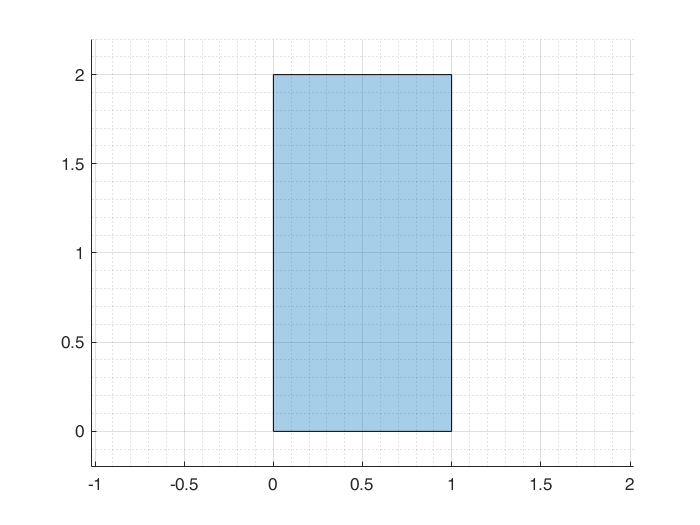

vert5 = rectangleVert([1,2]);
plot(polyshape(vert5'))
axSetup(); axis equal;

### higher density shapes

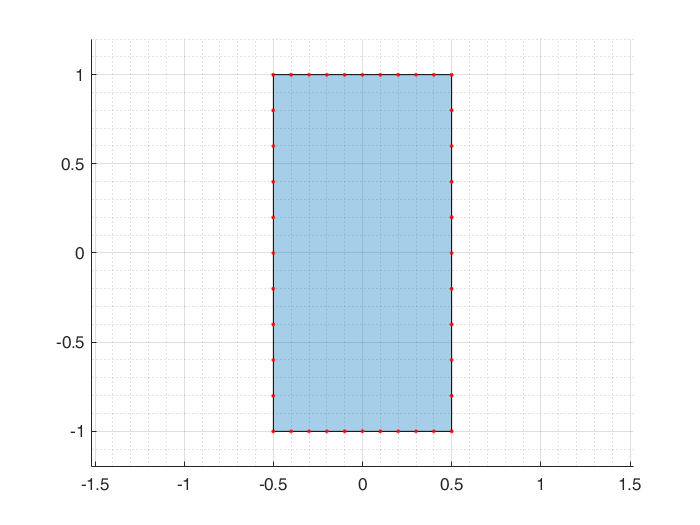

vert6 = rectangleVert([1,2],'coordinateSystem','c','density',9);
pgon1 = polyshape(vert6','Simplify',false);
plot(pgon1);
axSetup; axis equal;
line(vert6(1,:),vert6(2,:),'LineStyle','none','Marker','.','Color','r')

### with closed paramter set

vert6 = rectangleVert([1,2],'coordinateSystem','c','density',9,'loop','tight');
pgon2 = polyshape(vert6','Simplify',false);

## 3d vertices

vert7 = rectangleVert([1,2,2],'coordinateSystem','c','density',0,'loop','open','dimension',3);
pgon3 = polyshape(vert7(1:2,:)');
plot(pgon3);
axSetup; axis equal;

### connectivity map

[vert8,faces] = rectangleVert(2,'Density',2);

### connectivity map, closed loop shape

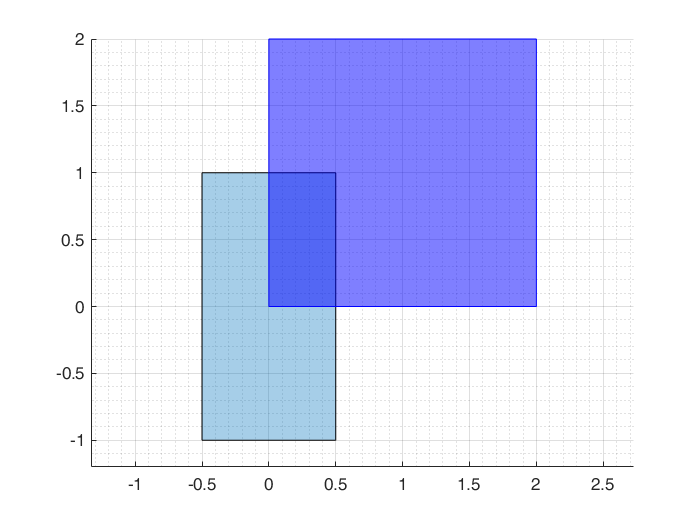

[vert8,faces] = rectangleVert(2,'Density',2,'loop','tight');
patch('Faces',faces,'Vertices',vert8','FaceColor','blue','FaceAlpha',0.5,'EdgeColor','blue')